# Assignment - 2 Submission Example: Student 1

close all; clear; clc;

## Open FEMM and make new document

openfemm(); newdocument(0);
path = 'E:\ELL851\Assignments\Assignment 2'; name_femm = 'Electromagnet.fem';
mi_saveas([name_femm]);
% Setting Preferences
mi_probdef(0,'millimeters','planar',1E-8,10,30,0);

## Geometry

% Draw core
x1 = 10; x2 = -10; y1 = 5; y2 = -5;
mi_drawrectangle(x1,y1,x2,y2);

% Draw Conductors
xc1 = 9; xc2 = -9; yc1 = 5.5; yc2 = 8.5;
mi_drawrectangle(xc1,yc1,xc2,yc2); %conductor 1

xc11 = 9; xc22 = -9; yc11 = -5.5; yc22 = -8.5;
mi_drawrectangle(xc11,yc11,xc22,yc22); %conductor 1

% Add material
mi_getmaterial('M-50'); mi_getmaterial('Air'); mi_getmaterial('10 SWG');

% Assign Core and Material
mi_clearselected(); mi_addblocklabel((x1+x2)/2,(y1+y2)/2);
mi_selectlabel((x1+x2)/2,(y1+y2)/2);
mi_setblockprop('M-50',1,0,'None',0,0,1);

mi_addcircprop('winding',10,1); mi_clearselected();
mi_addblocklabel((xc1+xc2)/2,(yc1+yc2)/2);
mi_selectlabel((xc1+xc2)/2,(yc1+yc2)/2);
mi_setblockprop('10 SWG',1,0,'winding',0,0,100);

mi_clearselected();
mi_addblocklabel((xc11+xc22)/2,(yc11+yc22)/2);
mi_selectlabel((xc11+xc22)/2,(yc11+yc22)/2);
mi_setblockprop('10 SWG',1,0,'winding',0,0,-100);

% Drawing boundary
xx1 = 40; xx2 = -40; yy1 = 0; yy2 = 0; angle = 180;
mi_drawarc(xx1,yy1,xx2,yy2,angle,1); mi_drawarc(xx2,yy2,xx1,yy1,angle,1);
mi_addboundprop('Air',0,0,0,0,0,0,0,0,0);
mi_selectarcsegment(0,40); mi_selectarcsegment(0,-40);
mi_setarcsegmentprop(5, 'Air', 0, 1);

% Assign Air
mi_clearselected(); mi_addblocklabel((x1+xx1)/2,0);
mi_selectlabel((x1+xx1)/2,0);
mi_setblockprop('Air',1,0,'<None>',0,0,1);

## Solution - Query 1

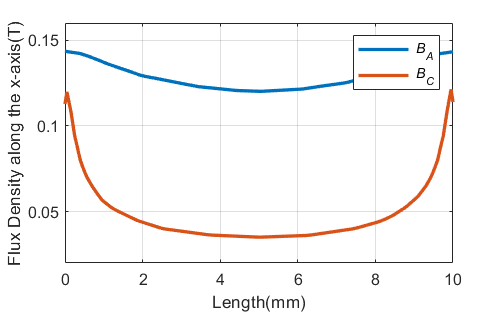

mi_analyze(1); mi_loadsolution();

k=1;
for i=(y2):0.05:(y1)
    B_xy = mo_getb(0,i);
    Ba_x(k) = B_xy(1); Ba_y(k) = B_xy(2);
    k=k+1;
end

k=1;
for i=(y2):0.05:(y1)
    B_xy = mo_getb(x1+0.1,i);
    Bc_x(k) = B_xy(1); Bc_y(k) = B_xy(2);
    k=k+1;
end

l1=0:.05:10;
plot(l1,Ba_x,l1,Bc_x, 'LineWidth',2)
xlabel('Length(mm)'); ylabel('Flux Density along the x-axis(T)'); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_A','\it B_C')

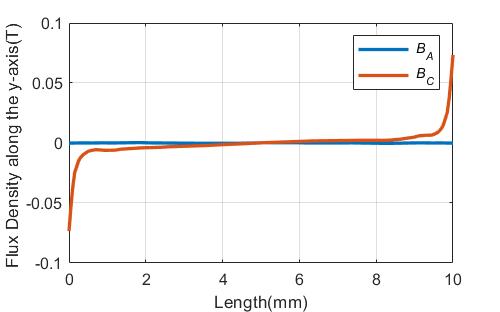

plot(l1,Ba_y,l1,Bc_y, 'LineWidth',2)
xlabel('Length(mm)'); ylabel('Flux Density along the y-axis(T) '); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_A','\it B_C')

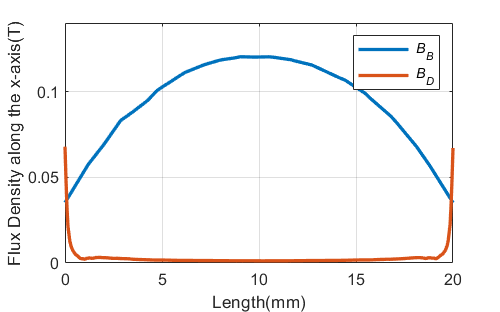

k=1;
for i=(x2):0.05:(x1)
    B_xy = mo_getb(i,0);
    Bb_x(k) = B_xy(1); Bb_y(k) = B_xy(2);
    k=k+1;
end

k=1;
for i=(x2):0.05:(x1)
    B_xy = mo_getb(i,y2-0.1);
    Bd_x(k) = B_xy(1); Bd_y(k) = B_xy(2);
    k=k+1;
end

l1=0:.05:20;
plot(l1,Bb_x,l1,Bd_x,'LineWidth',2) ; %hold on; plot(l1,Bb_y,l1,Bd_y); hold off
xlabel('Length(mm)'); ylabel('Flux Density along the x-axis(T)'); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_B','\it B_D')

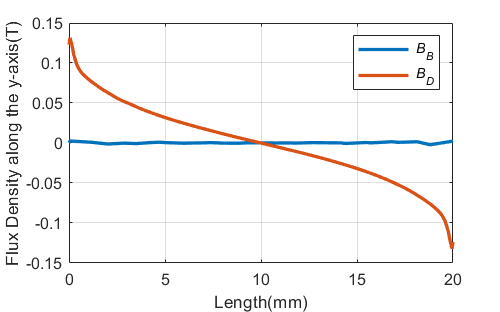

plot(l1,Bb_y,l1,Bd_y,'LineWidth',2)
xlabel('Length(mm)'); ylabel('Flux Density along the y-axis(T)'); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_B','\it B_D')

## Solution - Query 2

Current variation only (with fixed number of turns)

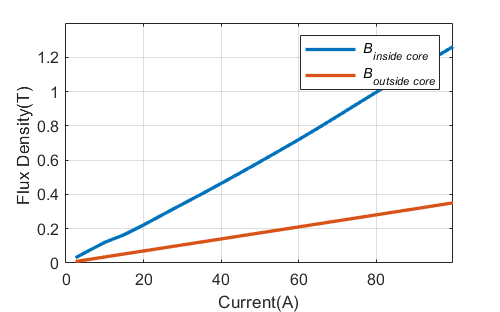

current = 0:5:100;
current(1)=2.5;

for i=1:length(current)
    mi_modifycircprop('winding',1,current(i))
    % Solve
    mi_analyze(1);
    mi_loadsolution();
    B_xy = mo_getb(0,0);
    Ba(i) = B_xy(1);
    B_xy = mo_getb(x1+0.1,0);
    Bc(i) = B_xy(1);
end

plot(current,Ba,current,Bc,'LineWidth',2)
xlabel('Current(A)'); ylabel('Flux Density(T) '); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_{inside core}','\it B_{outside core}')

Turns variation only (with fixed current)

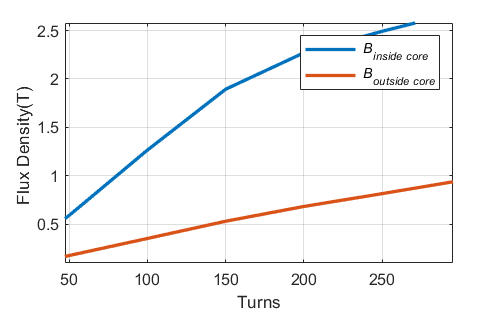

mi_modifycircprop('winding',10,0)
turns=0:50:300;
turns(1)=1;

for i=1:length(turns)
    
    mi_clearselected();
    mi_selectlabel((xc1+xc2)/2,(yc1+yc2)/2);
    mi_setblockprop('10 SWG',1,0,'winding',0,0,turns(i));

    mi_clearselected();
    mi_selectlabel((xc11+xc22)/2,(yc11+yc22)/2);
    mi_setblockprop('10 SWG',1,0,'winding',0,0,-turns(i));
    
    
    % Solve
    mi_analyze(1);
    mi_loadsolution();
    B_xy = mo_getb(0,0);
    Ba1(i) = B_xy(1);
    B_xy = mo_getb(x1+0.1,0);
    Bc1(i) = B_xy(1);
    
end

plot(turns,Ba1,turns,Bc1,'LineWidth',2)
xlabel('Turns'); ylabel('Flux Density(T) '); grid on; set(gcf,'Position',[0,0,400,250]);
legend('\it B_{inside core}',' \itB_{outside core}')

**Observations:**

--> Outside core flux density varies lineraly with current and turns as there is no saturation in air but inside as current and turns increase there is a hint of saturation.